# Laboratorio 1 Robótica: Análisis Geométrico Directo de Manipuladores

## Universidad Nacional de Colombia

## Alejandro Ojeda Olarte, Brayan Calderon, Mateo Rodriguez

## Parte I | Robot

El robot asignado es el modelo UR3 de la empresa Universal Robots.

### Características y modelo del robot

####            1. Busque información técnica del robot, obtenga catálogos de fabricante, presente en el informe:

####                 a) Imagen del robot.

####                 b)  Capacidad de carga.

####                 c)  Alcance vertical y horizontal.

####                 d)  Repetibilidad.

####                 e)  Gráfica(s) de espacio alcanzable.

####                 f)  Tabla de parámetros DH.

####                 g)  Qué software utiliza el fabricante para dise ̃no de celdas o programación.

####                 h)  ¿Qué otras características tiene? (Grado de protección IP, colaborativo, normas de seguridad etc.)

####                 i)  Haga un análisis del diagrama de la capacidad de carga.

####             2. Según las características anteriores explique para qué aplicaciones se usa este robot.

## Parte II | Modelos

### lniciando

#### Haciendo uso de MATLAB`® `y los toolboxes construya un modelo del robot o utilice uno disponible en los toolboxes y que corresponda al robot asignado.

####     1.Realice el análisis geométrico del robot asignado a través de DH modificado y utilice las funciones de RVC para construir un modelo en alambres.

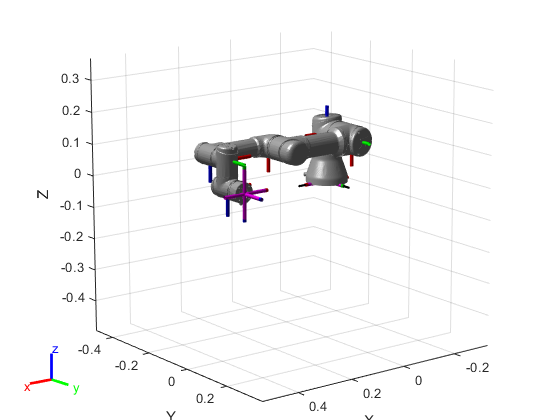

UR3=loadrobot("universalUR3");
show(UR3);

xlim([-0.336 0.528])
ylim([-0.491 0.373])
zlim([-0.497 0.368])
view([142.295 14.215])

showdetails(UR3)

--------------------
Robot: (10 bodies)

 Idx             Body Name                            Joint Name                            Joint Type             Parent Name(Idx)   Children Name(s)
 ---             ---------                            ----------                            ----------             ----------------   ----------------
   1             base_link                           world_joint                                 fixed                     world(0)   base(2)  shoulder_link(3)  
   2                  base            base_link-base_fixed_joint                                 fixed                 base_link(1)   
   3         shoulder_link                    shoulder_pan_joint                              revolute                 base_link(1)   upper_arm_link(4)  
   4        upper_arm_link                   shoulder_lift_joint                              revolute             shoulder_link(3)   forearm_link(5)  
   5          forearm_link                           e

####     2.Considerando el robot asignado, construya el modelo del robot utilizando RST.

####     3.Compare los dos métodos.

### Modelo Geométrico Directo 

####     1. Halle el modelo geométrico directo de su robot asignado usando DH modificado.

####     2.  Haciendo uso del modelo directo haga una representación del espacio de trabajo alcanzable del robot.

L(1) = Link([0 0.152 0 0],'modified');

Unrecognized function or variable 'Link'.

L(2) = Link([0 0.120 0 pi/2 0 pi/2],'modified');
L(3) = Link([0 0 0.244 0],'modified');
L(4) = Link([0 -0.010 0.213 0 0 -pi/2],'modified');
L(5) = Link([0 0.083 0 -pi/2],'modified');
L(6) = Link([0 0 0 pi/2],'modified');
R = SerialLink(L,'name','Universal Robot UR3')
R.plot([0 0 0 0 0 0],'noa','jvec','view',[20 30]);
trplot(R.base*L(1).A(0)*L(2).A(0)*L(3).A(0)*L(4).A(0)*L(5).A(0),'rgb')
endeffect=R.base*L(1).A(0)*L(2).A(0)*L(3).A(0)*L(4).A(0)*L(5).A(0);
position=endeffect(1:3,4)

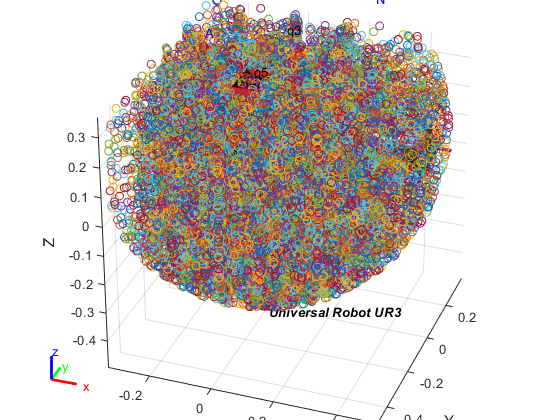

s = 2*pi;
step=0.5;
hold on
for i = 0:step:s
    for j = 0:step:s
        for k = 0:step:s
            for m = 0:step:s
                for n = 0:step:s
                    endeffect=R.base*L(1).A(i)*L(2).A(j)*L(3).A(k)*L(4).A(m)*L(5).A(n)*L(6).A(0);
                    position=endeffect(1:3,4);
                    plot3(position(1),position(2),position(3),'o');
                end
            end
        end
    end
end


% th1 = (-pi/2:0.05:pi/2) ;
% th2 = (-pi/2:0.05:pi/2);
% th3 = (-pi/2:0.05:pi/2) ;
% th4 = (-pi/2:0.05:pi/2) ;
% th5 = (-pi/2:0.05:pi/2) ;
% %th6 = (-pi/2:0.05:pi/2) ;
% 
% q = {th1,th2,th3,th4,th5};
% plotworkspace(L,q)

####     3.  Con la hoja técnica del robot, el fabricante provee puntos de calibración. Con la ayuda de la cinemática directa verifique dichos puntos.

####     4.  Haga uso de las funciones de cinemática directa de ambos toolboxes y compruebe los resultados anteriores.

####     5.  Compare los métodos.

####     6.  Exprese la pose del efector en matriz de cosenos directores.

####     7.  Exprese la pose del efector final en coordenadas generalizadas del efector final.

####     8.  Elija uno de los métodos anteriormente usados y desarrolle una GUI que permita mover cada articulación mediante controles tipo Slider, visualizar el robot y la posición del efector final.

####     9.  En el informe incluya capturas de pantalla verificando las posiciones EF y las articulaciones.